# ISONE zonal price data cleaning

## Import ISONE price data

datetime.setDefaultFormats('default','MM/dd/yyyy HH:mm:ss');
% Import hourly zonal LBMP data in 2019 whole year
% Run this under the model_code directory or change the priceFileDir manually
priceFileDir = "..\data\2019_LMP_ISONE\";
priceFileName = "WW_DALMP_ISO_2019*.csv";
priceDataStore = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importPriceISONE, "UniformRead", true);
priceAll = readall(priceDataStore);
clear priceDataStore;

## Select the date and hours with low effect of congestion and loss

% Take absolute value of marginal loss cost and marginal congestion cost
priceAll.AbsLossCost = abs(priceAll.MarginalLossComponent);
priceAll.AbsCongCost = abs(priceAll.CongestionComponent);

% Calculate hourly total loss cost and total congestion cost
hourlyPriceSummary = groupsummary(priceAll, "DateTime", "sum", ["LocationalMarginalPrice","AbsLossCost", "AbsCongCost"]);
% Add up the total loss cost and total congestion cost
hourlyPriceSummary.sum_AbsLossCongCost = hourlyPriceSummary.sum_AbsLossCost + hourlyPriceSummary.sum_AbsCongCost;
% Calculate the ratio of total loss and congestion cost over sum of LBMP
% This is equal to the ratio of average loss and congestion cost over
% average LBMP over the zones
hourlyPriceSummary.CLFactor = hourlyPriceSummary.sum_AbsLossCongCost./hourlyPriceSummary.sum_LocationalMarginalPrice;
hourlyPriceSummary.averageLMP = hourlyPriceSummary.sum_LocationalMarginalPrice/8;
hourlyPriceSummary = movevars(hourlyPriceSummary, "averageLMP", "Before","CLFactor");
hourlyPriceSummary = removevars(hourlyPriceSummary, ["sum_AbsCongCost", "sum_LocationalMarginalPrice", "sum_AbsLossCost", "sum_AbsLossCongCost", "GroupCount"]);
hourlyPriceSummary.Date = datetime(year(hourlyPriceSummary.DateTime), month(hourlyPriceSummary.DateTime), day(hourlyPriceSummary.DateTime), "Format","MM/dd/yyyy");
hourlyPriceSummary.Hour = hour(hourlyPriceSummary.DateTime);
isSpring = ismember(month(hourlyPriceSummary.DateTime), [3,4,5]); 
isSummer = ismember(month(hourlyPriceSummary.DateTime), [6,7,8]);
isAutumn = ismember(month(hourlyPriceSummary.DateTime), [9,10,11]); 
isWinter = ismember(month(hourlyPriceSummary.DateTime), [12,1,2]);
Season = zeros(size(hourlyPriceSummary.DateTime, 1), 1);
Season(isSpring) = 1;
Season(isSummer) = 2;
Season(isAutumn) = 3;
Season(isWinter) = 4;
hourlyPriceSummary.Season = categorical(Season);

## Find the date and hours when CLFactor is less than 1%, 3533 out of 8760 hours are selected

selDateTimePrice = hourlyPriceSummary(hourlyPriceSummary.CLFactor <= 0.01, :)

selDateTimePrice = 3533×6 table
         DateTime          averageLMP    CLFactor        Date       Hour    Season
    ___________________    __________    _________    __________    ____    ______

    01/01/2019 01:00:00      20.396      0.0097444    01/01/2019      1       4   
    01/01/2019 02:00:00      18.829      0.0079002    01/01/2019      2       4   
    01/01/2019 03:00:00      19.054      0.0084629    01/01/2019      3       4   
    01/01/2019 04:00:00      17.759      0.0069684    01/01/2019      4       4   
    01/01/2019 05:00:00      20.144      0.0087496    01/01/2019      5       4   
    01/01/2019 06:00:00      20.579      0.0075928    01/01/2019      6       4   
    01/01/2019 07:00:00      22.927      0.0085051    01/01/2019      7       4   
    01/01/2019 0

## Subset the original and filtered price dataset by seasons

hourlyPriceSeasons = cell(4, 1);
selPriceSeasons = cell(4, 1);
for s=1:4
    hourlyPriceSeasons{s} = hourlyPriceSummary(hourlyPriceSummary.Season == categorical(s), :);
    selPriceSeasons{s} = selDateTimePrice(selDateTimePrice.Season == categorical(s), :);
end
Seasons = ["Spring", "Summer", "Autumn", "Winter"];

## Plot the original and filtered price data in seasons

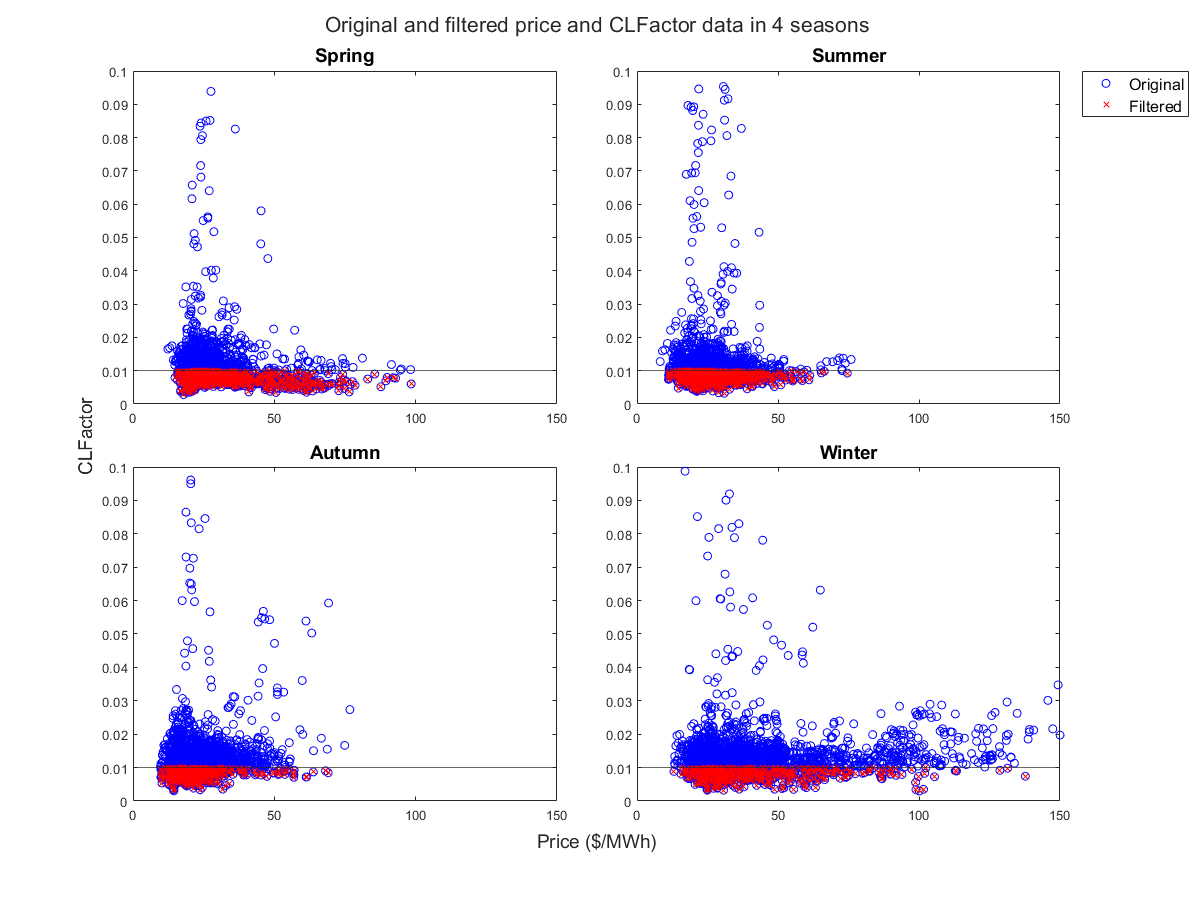

figure;
t = tiledlayout(2, 2, "TileSpacing","compact");
for s=1:4
    nexttile;
    hourlyPriceTable = hourlyPriceSeasons{s};
    selPriceTable = selPriceSeasons{s};
    hold on;
    % Plot original price vs CLFactor data
    scatter(hourlyPriceTable.averageLMP, hourlyPriceTable.CLFactor, 'bo');
    % Plot filtered price vs CLFactor data
    scatter(selPriceTable.averageLMP, selPriceTable.CLFactor, 'rx');
    axis([0, 150, 0, 0.1]);
    title(Seasons(s), "FontSize", 14);
    yline(0.01);
    hold off; box on;
    if s==2
        legend(["Original", "Filtered"], "Location","bestoutside", "FontSize", 12);
    end
end
xlabel(t, "Price ($/MWh)", "FontSize", 14);
ylabel(t, "CLFactor", "FontSize", 14);    
title(t, "Original and filtered price and CLFactor data in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/priceSeasons.png");

## Write the selected date and hours into a file

save("../model_output/mat_files/selDateTimePriceISONE.mat", "selDateTimePrice", "-mat");
save("../model_output/mat_files/PriceOrigFiltSeasons.mat", "selPriceSeasons", "hourlyPriceSeasons", "-mat");